# Lab 1 report (100 points total)

# Name: XXX, SID: xxxxxxxx

# 2.3 (5'': means 5 points)

A = [pi;sqrt(2);exp(1)]

A =     3.1416
    1.4142
    2.7183


B = [1;5;7]

B =      1
     5
     7


C = A'*B  

C = 29.2406

# 2.5 (10'')

clear all
A = [pi;sqrt(2);exp(1)]

A =     3.1416
    1.4142
    2.7183


B = [1;5;7]

B =      1
     5
     7


D = 0;
%Implements a "for loop" to compute D
for i = 1:3
    D = D + A(i)*B(i);
end
D

D = 29.2406

# 2.6 (20'')

Plot y as a function of x. N = 200, 5, 10.

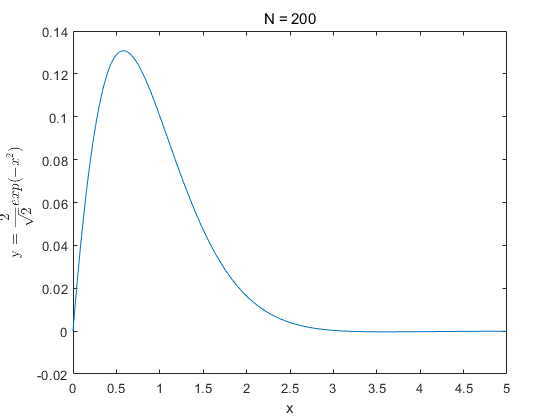

plotting(200)

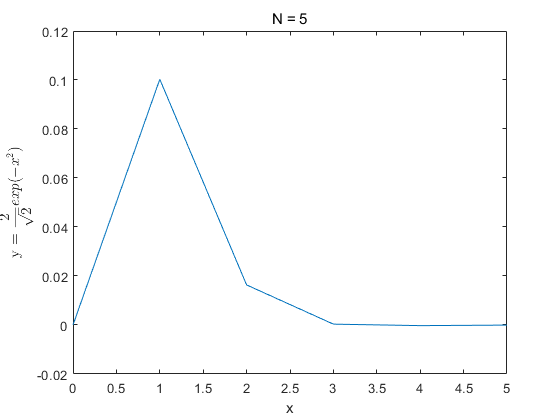

plotting(5)

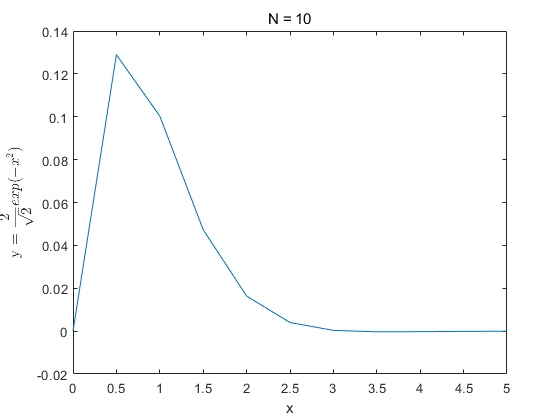

plotting(10)

# 2.7

## (a) (5'')

f = @(x) myfun(x);

Compute $Q = \int^5_0{f(x)dx}$.

Q = integral(f, 0,5) 

Q = 0.1587

## (b) (10'')

**i)**

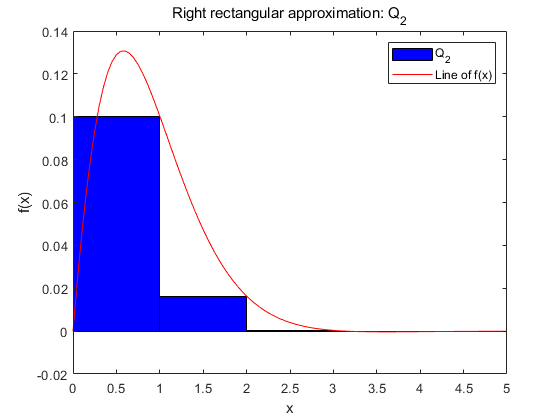

%Compute the bar by 5 intervals
N = 5;
x_bar = 1:5/N:5;
y_bar = myfun(x_bar);
%Compute f(x)
x = 0:5/100:5;%Generate x by N
y = myfun(x);

figure
%plot the bar
bar(x_bar-0.5,y_bar,1,'blue')
xlim([0,5])
hold on%hold on the same figure
%plot f(x)
plot(x,y,'red')
title('Right rectangular approximation: Q_2')
xlabel('x');ylabel('f(x)')
legend('Q_2','Line of f(x)')

**When dx_i getting smaller, the area of trapezoid or rectangular will closer to the area of f(x) in range dx_i-1 to dx_i.**

**ii) A&B (10'')**


$$\begin{array}{l}
Q_3 =\sum_{i=1}^{N-1} \left\lbrace f\left(x_i \right){\textrm{dx}}_{i\;\;} +0\ldotp 5\left(f\left(x_{i+1} \right)-f\left(x_i \right)\right){\textrm{dx}}_i \right\rbrace \\
\;\;\;\;\;=\sum_{i=1}^{N-1} \left\lbrace f\left(x_i \right)\frac{{\textrm{dx}}_{i\;\;} }{2}+f\left(x_{i+1} \right)\frac{{\textrm{dx}}_i }{2}\right\rbrace \\
\;\;\;\;\;=\sum_{i=1}^{N-1} f\left(x_i \right)\frac{{\textrm{dx}}_{i\;\;} }{2}+\sum_{i=2}^N f\left(x_i \right)\frac{{\textrm{dx}}_{i-1\;\;} }{2}\\
\;\;\;\;\;=\frac{Q_1 +Q_2 }{2}\\
\;\;\;\;\;=\frac{1}{2}\left\lbrace f\left(x_1 \right){\textrm{dx}}_{1\;} +f\left(x_2 \right){\textrm{dx}}_{1\;} +f\left(x_2 \right){\textrm{dx}}_{2\;} +f\left(x_3 \right){\textrm{dx}}_{2\;} +\ldotp \ldotp \ldotp +f\left(x_{N-1} \right){\textrm{dx}}_{N-1} +f\left(x_N \right){\textrm{dx}}_{N-1} \right\rbrace \\
\;\;\;\;\;=\frac{1}{2}\left\lbrace f\left(x_1 \right){\textrm{dx}}_{1\;} +2f\left(x_2 \right){\textrm{dx}}_{2\;} +\ldotp \ldotp \ldotp +2f\left(x_{N-1} \right){\textrm{dx}}_{N-1} +f\left(x_N \right){\textrm{dx}}_{N-1} \right\rbrace \\
\;\;\;\;\;=\frac{1}{2}f\left(x_1 \right){\textrm{dx}}_{1\;} +\sum_{i=2}^{N-1} f\left(x_i \right){\textrm{dx}}_{i\;\;} +\frac{1}{2}f\left(x_N \right){\textrm{dx}}_{N-1} 
\end{array}$$


## (c) (10'')

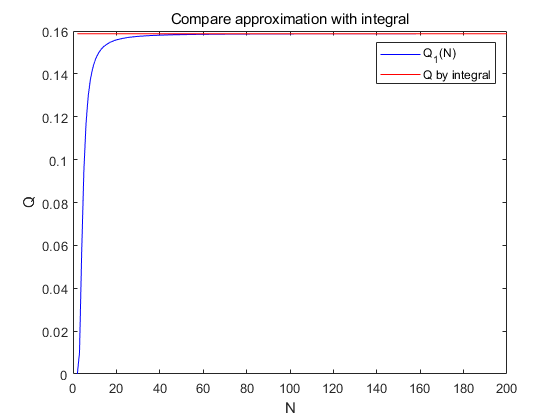

N = 2:200;
Q1 = NaN(length(N),1);
for i = 1:length(N)
    dx = 5/(N(i)-1);
    x = 0:dx:5;
    y = myfun(x);
    A = [ones(N(i)-1,1);0];
    Q1(i) = y*A*dx;
end
figure
plot(N,Q1,'blue')
hold on
plot(N,ones(1,length(N))*Q,'red') %Plot Q (Since Q is one number, repeat Q.)
title('Compare approximation with integral')
xlabel('N');ylabel('Q')
legend('Q_1(N)','Q by integral')

**As N increasing, the approximation will converge to the integral value.**

## (d) (30'')

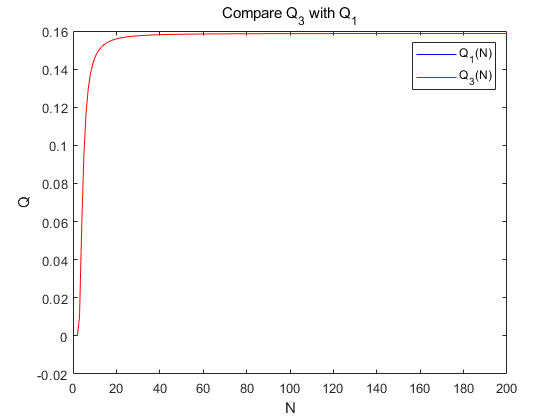

(10'')

Q3 = NaN(length(N),1);
for i = 1:length(N)
    dx = 5/(N(i)-1);
    x = 0:dx:5;
    y = myfun(x);
    % Q3 = Q1/2 + Q2/2
    A = [ones(N(i)-1,1);0]/2+[0;ones(N(i)-1,1)]/2;
    Q3(i) = y*A*dx;
end
figure
plot(N,Q1,'blue')
hold on
plot(N,Q3,'red')
legend('Q_1(N)','Q_3(N)')
title('Compare Q_3 with Q_1')
xlabel('N');ylabel('Q')

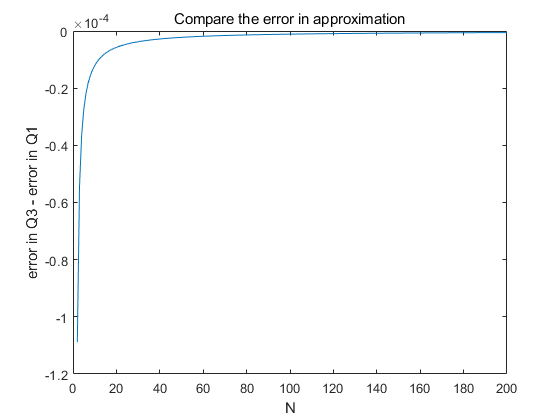

(5'')
error_Q1 = Q1-Q;
error_Q3 = Q3-Q;
figure
plot(N,error_Q3 - error_Q1)
title('Compare the error in approximation')
xlabel('N');ylabel('error in Q3 - error in Q1')

**Rate of convergence (5'')**

u_Q3 = (Q3(end)-Q)/(Q3(end-1)-Q) %Rate of convergence for Q3 

u_Q3 = 0.9900

u_Q1 = (Q1(end)-Q)/(Q1(end-1)-Q) %Rate of convergence for Q1 

u_Q1 = 0.9899

**u_Q3>u_Q1, Q3 is the better algorithm.  (5'')**

# **Function define**

function y = myfun(x)
    y = sin(x)./(1+exp(2*x)); % x.^2 or x.*x
end

function plotting(N)
    x = 0:5/N:5;%Generate x by N
    y = myfun(x);
    figure
    plot(x,y)
    xlabel('x');ylabel('y = $$\frac{2}{\sqrt{2}}exp(-x^2)$$','Interpreter','latex')
    title(['N = ',num2str(N)])
end